# Control and Instrumentation Lab Assignment 4

**SWARNENDU PAUL 19EE3FP18**

**Q5.**

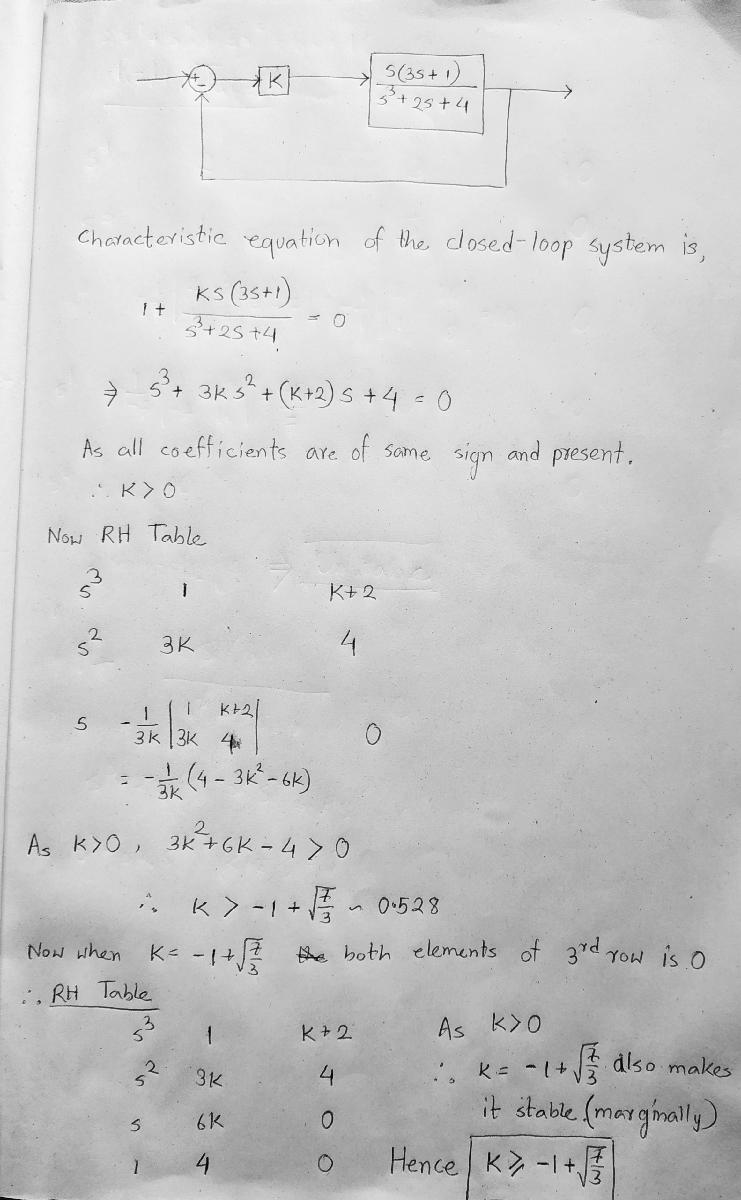

From the above solution, for $K\geq-1+\sqrt{\frac{7}{3}}$ the system is stable. For $K=-1+\sqrt{\frac{7}{3}}$ it is marginally stable. 

Now we will verify it using the rhc function we have found by determining stability for variable $K$.

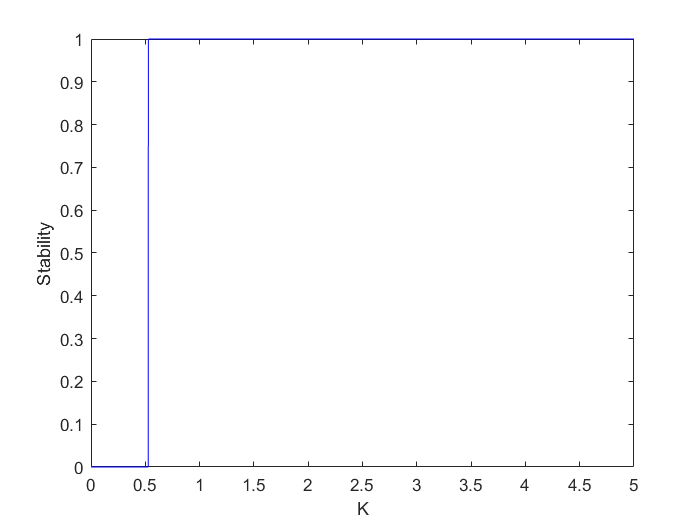

k=1e-3:1e-3:5;
y=zeros(size(k));
for i =1:length(k)
    y(i)=rhc([1,3*k(i),k(i)+2,4],0);
end
figure;
plot(k,y,"b-")
xlabel("K");
ylabel("Stability");

As observed from the calculation, the system becomes stable when $K\geq 0.528$

**Q6.**

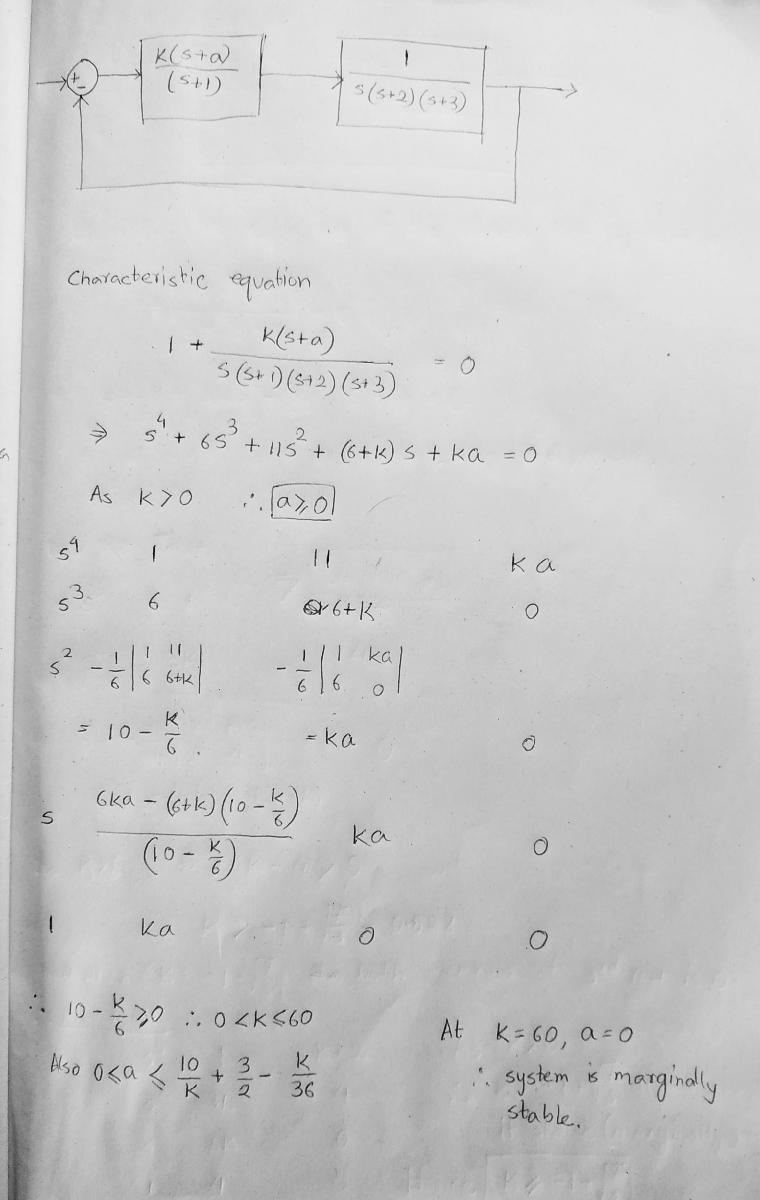

so given system is stable when 


$$0<K\leq60$$



$$0\leq a\leq \frac{10}{k}+\frac{3}{2}-\frac{k}{36}$$
 

so when $K=60$, $a=0$ which makes the system marginally stable with pole at 0.

when $K\to0$ range of a becomes very large so it is not possible to plot the whole stability region with the rhc fuction we defined. 

Hence, we will find the stability region for $K\in(0,60]$ and $a\in[0,10]$

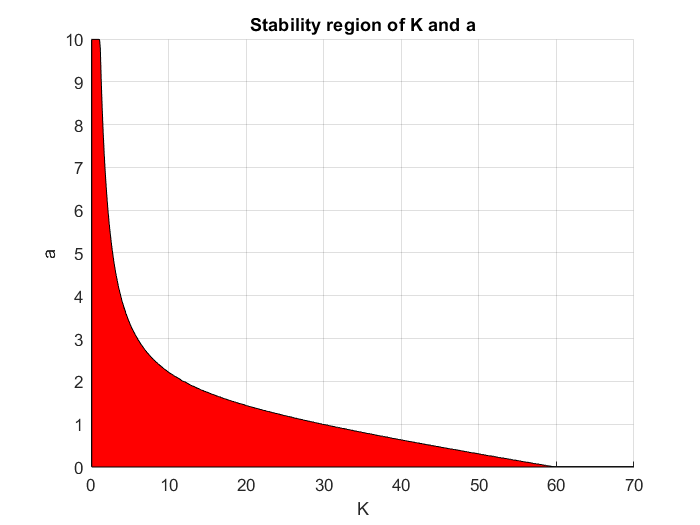

k=0.1:0.1:70;
a=0:0.01:10;
y=zeros(size(k));
for i=1:length(k)
    for j=1:length(a)-1
        c=rhc([1,6,11,6+k(i),k(i)*a(j)],0);
        b=rhc([1,6,11,6+k(i),k(i)*a(j+1)],0);
        if(c~=b)||(b==1 && j==length(a)-1)
            y(i)=a(j);
        end
    end
end
figure;
patch([k,fliplr(k)],[y,zeros(size(y))],'r')
xlabel("K");
ylabel("a");
title("Stability region of K and a");
grid on

Now we need to determine the impact on Data head position response if we decrease the value of a for a fixed value of K.

The given model is designed in simulink(**model6.slx**) with $K=10$ and we will check the output response for variable values of a from 2 to 0. As the system is stable in this region.

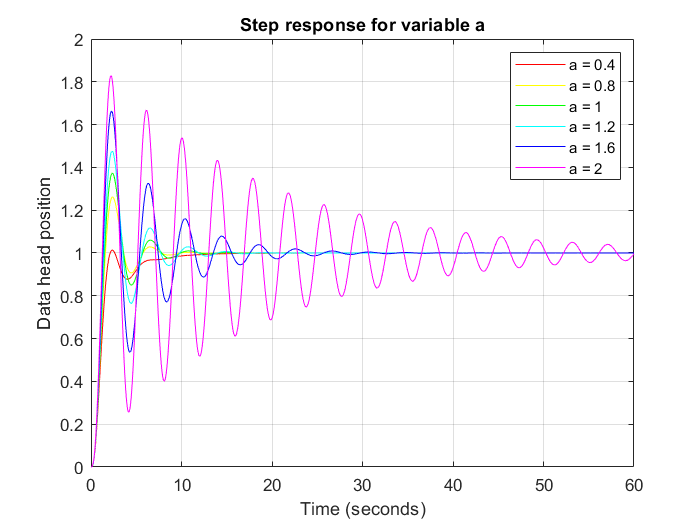

A=[0.4,0.8,1,1.2,1.6,2];
CM=hsv(6);
figure;
for i=1:6
    model6a=A(i);
    out=sim("model6.slx");
    plot(out.c,"Color",CM(i,:),"DisplayName",strcat("a = ",num2str(model6a)));
    hold on
end
hold off
legend
grid on
ylabel("Data head position");
title("Step response for variable a");

From the simulation, we observe that reducing the value of a, reduces the overshoot and oscillation of the system. For higher value of a the system reaches the steady state value faster but it oscillates for long time. 